# The celestial package

# in the astronomy & astrophysics toolbox for MATLAB

## Description:

The `celestial` package contains many sub packages that contain functions to calculate and manipulate coordinates, celestial mechanics, calculate ephemerides and projection, display maps, Earth coordinates and gravity, time, and more. Additional related functions are in the `convert` and `constant` static classes, and in the `OrbitalEl` class.

To view all the sub packages type: "celestial`.`" followed by <tab>.

To avoid using the "`celestial.coo.sphere_dist`" syntax, you can use:

import celestial.coo.*
help sphere_dist

This file is accessible through` manual.celestial`

## Credit

If you are using this code or products in your scientific publication please give a reference to [Ofek (2014; ascl.soft 07005)](http://adsabs.harvard.edu/abs/2014ascl.soft07005O).

## License

Unless specified otherwise this code and products are released under the GNU general public license version 3.

## Installation

See[ http://weizmann.ac.il/home/eofek/matlab/doc/install.html ](http://webhome.weizmann.ac.il/home/eofek/matlab/doc/install.html)for installation instruction and additional documentation.

# List and description of the subpackages

## The Coo package

General coordinates utilities, manipulation and conversion. Including treatment of aberration of light, airmass, angles, proper motion, coordinate conversion, coordinate formats, cosine direction, interpolation, refraction, light deflection, precession, nutation, obliquity, spherical coordinates, spherical distance, and more.

**Some highlights:**

celestial.coo.convertdms is a general utility for coordinates format manipulation:

% convert sexagesimal coordinates to degrees
celestial.coo.convertdms('15:10:56.1','SH','d')

ans =        227.73


% convert sexagesimal vector to radians
celestial.coo.convertdms([ -1 0 10 56.1],'D','r')

ans =    -0.0031809


Convert zenith angles to airmass using the Hardie formula:

AM=celestial.coo.hardie([1;1.1])

AM =        1.8467
       2.1968


Earth nutation:

[N,NM]=celestial.coo.nutation(2451545+(1:2)');

General coordinates conversion:

% conversion of [RA Dec] in radians from J2000.0 to ecliptic
C=celestial.coo.coco(rand(4,2),'j2000.0','e')

C =       0.68468     -0.22087
      0.49706      0.22655
      0.35204      0.33219
      0.81405      0.49424


% Galactic to super galactic, input and output in degrees
C=celestial.coo.coco([100 10],'g','S','d','d')

C =          7.77       37.823


Generation of rotation matrix for coordinate conversion:

% Super Galactic to Equatorial J2000.0.
R=celestial.coo.rotm_coo('SGg')

R =      -0.73574    -0.074554      0.67315
      0.67726    -0.080991      0.73127
            0      0.99392      0.11008


Spherical distances:

tic;
[D,P]=celestial.coo.sphere_dist(rand(1e5,1),rand(1e5,1),[10 0 0],[1 40 0 0]);
toc

Elapsed time is 0.035490 seconds.


Calculate sky area observable during the night above a specific airmass, and assuming each field is observable for at least TimeVis hours.

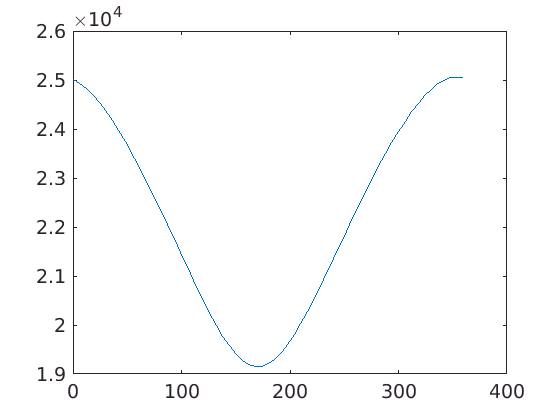

VecJD = celestial.time.julday([1 1 2000])+(1:6:366)';
Lat   = 33.*pi./180;
AM    = 1.8;
TimeVis = 0;
for I=1:1:numel(VecJD)
    [SkyArea(I),LON(I)]=celestial.coo.sky_area_above_am(VecJD(I),Lat,AM,TimeVis);
end
plot(VecJD-VecJD(1),SkyArea)

Atmospheric refraction:

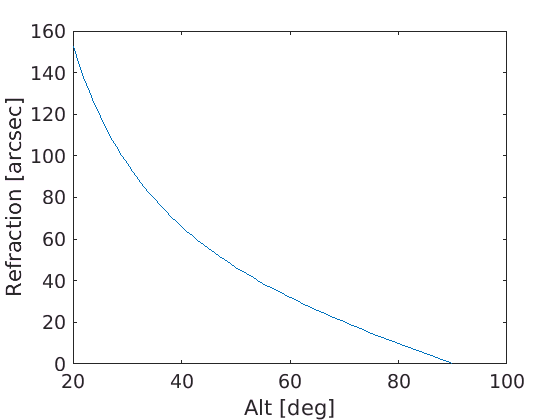

RAD = 180./pi;
% atmospheric refraction as a function of altitude
Alt = (20:1:90)./RAD;
R   = celestial.coo.refraction(Alt);
plot(Alt.*RAD,R.*RAD.*3600)
xlabel('Alt [deg]');
ylabel('Refraction [arcsec]');

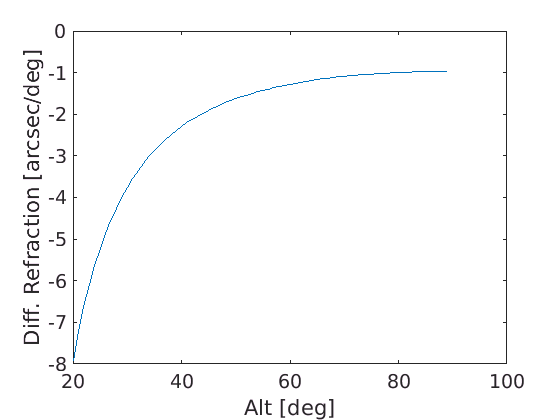

% differntial refraction
plot(Alt(1:end-1).*RAD,diff(R).*RAD.*3600)
xlabel('Alt [deg]');
ylabel('Diff. Refraction [arcsec/deg]');

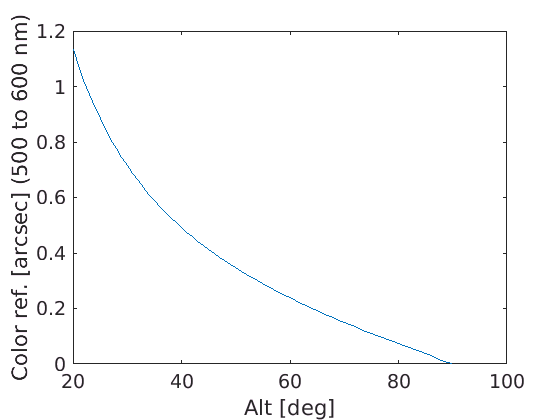

% color refraction as a function of altitude
[R5,N]=celestial.coo.refraction_wave(Alt,5000);
[R6,N]=celestial.coo.refraction_wave(Alt,6000);
plot(Alt.*RAD,(R5-R6).*RAD.*3600)
xlabel('Alt [deg]');
ylabel('Color ref. [arcsec] (500 to 600 nm)');

## The time package

The time sub-package is a collection of tools fot time manipulation and conversion.

Additional relevant functions are available in the convert static class and in the `AstTime` class. Specifically, the `AstTime` class contains excess to most of the functions in the `celestial.time` package and additional powerful options.

**Basic time conversions**

The following example shows some basic time conversions:

import celestial.time.*
% Calculate the JD now:
julday

ans =    2.4578e+06


% calculate the JD for some dates in [D M Y Frac_of_day] format
julday([1 1 2015 0.5; 1 2 2015 0.7])

ans =     2.457e+06
   2.4571e+06


% calculate the JD for a date in [D M Y H M S] format
julday([1 1 2015 18 30 45])

ans =     2.457e+06


% calculate the JD from an ISO string
julday('2015-01-01T18:30:45.0')

ans =     2.457e+06


% or from several ISO strings
JD = julday({'2015-01-01T18:30:45.0','2016-02-01T12:30:15'})

JD =     2.457e+06
   2.4574e+06



% convert JD to date in [D M Y Frac] format
jd2date(JD)

ans =             1            1         2015      0.77135
            1            2         2016      0.52101


% convert JD to date in [D M Y H M S] format
jd2date(JD,'H')

ans =             1            1         2015           18           30           45
            1            2         2016           12           30           15



% convert jd to MJD
MJD=jd2mjd(JD)

MJD =         57024
        57420


% convert MJD to JD
JD=mjd2jd(MJD)

JD =     2.457e+06
   2.4574e+06


for more general time conversion see also `convert.time` and the `AstTime` class `convert` method.

**Sidereal time**

To calculate sidereal time:

import celestial.time.*
% input is JD in UT1 time scale
JD = julday([1 1 2016])+(0:1:10)';
% calculate the GMST - output is in fraction of day
LST = lst(JD,0)

LST =       0.27803
      0.28077
      0.28351
      0.28624
      0.28898
      0.29172
      0.29446
       0.2972
      0.29993
      0.30267
      0.30541


% calculate the Greenwich Apparent Sidereal Time
LST = lst(JD,0,'a')

LST =       0.27803
      0.28077
      0.28351
      0.28624
      0.28898
      0.29172
      0.29446
       0.2972
      0.29993
      0.30267
      0.30541


% Mean sidereall time at longitude 35 def
LST = lst(JD,35.*pi./180)

LST =       0.37525
      0.37799
      0.38073
      0.38347
       0.3862
      0.38894
      0.39168
      0.39442
      0.39716
      0.39989
      0.40263


**Time systems**

The `celestial.time.wget_eop`, and `celestial.time.wget_tai_utc` are responsible for retrieving the Earth rotatiopn parameters and time system information from online [Intenational Earth Rotation Service (IERS)](https://www.iers.org/IERS/EN/Home/home_node.html). These functins have two modes: 'get' and 'use'. The 'get' option gets the Earth rotation parameters from the IERS website, store it locallly and read it. The 'use' option use the local files. The local files will be stored in your '/matlab/data/SolarSys/' directory.

% Store a local copy of The EOP file:
EOP=celestial.time.wget_eop('get');
% Store a local copy of TAI/UTC file:
TAI_UTC=celestial.time.wget_tai_utc('get');

Now you can retrieve parameters related to various time systems:

% DeltaT = TT-UT1 (after 1984)
DeltaT=celestial.time.delta_t([2451545;celestial.time.julday])

DeltaT =        63.829
       68.624


% TDB-TT
Diff=celestial.time.tdb_tdt(2451545)

Diff =   -7.2659e-05


% TAI-UTC and TT-UTC:
[TAImUTC,TTmUTC]=celestial.time.tai_utc([0;2451545])

TAImUTC =    NaN
    32


TTmUTC =           NaN
       64.184


% UT1-UTC and Earth Oreientation Parameters
[UT1mUTC,EOP]=celestial.time.ut1_utc(2451545)

UT1mUTC =       0.35504


EOP =           Cat: [16519×27 double]
          Col: [1×1 struct]
    UnitsCell: {'day'  ''  ''  ''  'mas'  'mas'  'mas'  'mas'  's'  's'  'ms'  'ms'  'mas'  'mas'  'mas'  'mas'  'mas'  'mas'  'mas'  'mas'  'mas'  'mas'  'mas'  'mas'  'mas'  'mas'  'mas'}


**Calendars**

Examples related to calendars:

% number of days in Month in Feb 2000:
celestial.time.days_in_month(2000,2)

ans =     29


% Date of Easter in 2000:
celestial.time.easter_date(2000)

ans =           23           4        2000


## The Earth package

This package contains function for geodetic to geocentric coordinates conversion (`celestial.Earth.geod2geoc`, `celestial.Earth.geoc2geod`) and reference ellipsoid (`celestial.Earth.refellipsoid`).

To calculate the Earth gravity field potential:

[V,W,EGM]=celestial.Earth.earth_gravity_field(6731e5,1,1);

## The htm package

The `htm` sub-package contains some basic function to construct and treat an Hierarchical Triangular Mesh (HTM) trees.

## The Kepler package

The `Kepler` sub-package contains functions related to the two body problem and the Kepler Equation. Additional capabilities and tools are available in the OrbitalEl class that is a container for orbital elements (see separate documentation).

Several highlights - solving the Kepler equation:

% solve the Kepler equation for elliptic orbit simultanously for 1e6 objects:
t = rand(1e6,1);  % t-T (day)
q = rand(1e6,1);  % q (au)
e = rand(1e6,1);   % e
tic;
[Nu,R,E]=celestial.Kepler.kepler_elliptic(t,q,e);
toc

Elapsed time is 0.139829 seconds.


See also: `celestial.Kepler.kepler_parabolic, celestial.Kepler.kepler_hyperbolic, celestial.Kepler.kepler_elliptic_fast, celestial.Kepler.kepler_lowecc`.

Additional functions related to the Kepler equation are: `celestial.Kepler.dnu_dt, celestial.Kepler.eccentric2true_anomaly, celestial.Kepler.true2eccentric_anomaly, celestial.Kepler.trueanom2pos, celestial.Kepler.trueanom2vel`. 

The `celestial.Kepler.gauss_grav_const` function can be used to generate the gravitational constant required for problems not in our Solar System (note that this is an optional input of e.g., `celestial.Kepler.kepler_elliptic`).

Some additional functions are also available.

## The map package

The c`elestial.ma`p sub-package contains utilities for plotting star charts. Most notably: `celestial.map.plot_monthly_smap` which can be used to plot star maps visible from the local horizon. This function is described in detailed in `manual.plot_monthly_smap`.

## The proj package

The `celestial.proj` sub-package contain function for mapping transformations and projections. All the major projections are included.

## The SolarSys package

The celestial.SolarSys sub-package is a collection of functions for Solar System related ephemeris. The package have access to low and high accuracy ephemeris.

Some highlights:

**Low accuracy ephemeris**

For low-accuracy (0.01 deg in longitude) ephemeris of the Sun use: celestial.SolarSys.suncoo:

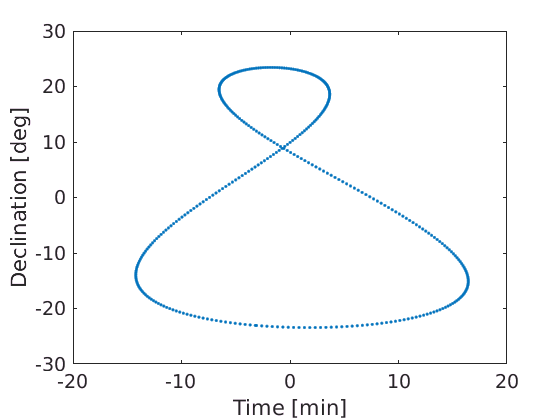

JD = celestial.time.julday([1 1 2015])+(0:1:365)';
% Calculate apparent coordinate of the Sun in 2015
[RA,Dec,R,sl,ET]=celestial.SolarSys.suncoo(JD,'a');
% plot the analema
ET(ET>900) = ET(ET>900)-1440;
plot(ET,Dec.*180./pi,'.')
xlabel('Time [min]');
ylabel('Declination [deg]');

**Low-accuracy ephmeris of the Moon:** calculate the Moon angular distance from some celestial point:

% Convert coordinates of fixed position to radians
RA  = celestial.coo.convertdms('15:45:12.1','SH','r');
Dec = celestial.coo.convertdms(15.1,'d','R')

Dec =       0.26354


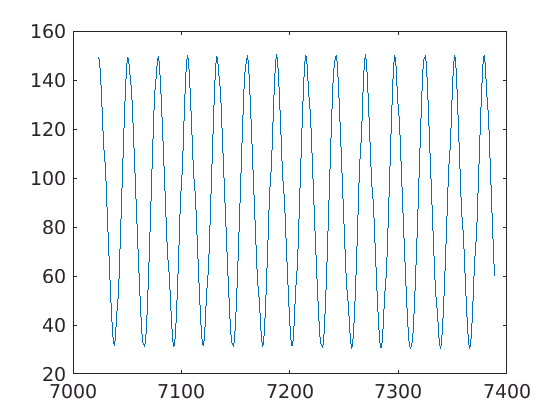

% Moon coordinatesv from Israel
JD = celestial.time.julday([1 1 2015])+(0:1:365)';
[MoonRA,MoonDec,HP]=celestial.SolarSys.mooncool(JD,[35 32].*pi./180);
D = celestial.coo.sphere_dist(MoonRA,MoonDec,RA,Dec);
plot(JD-2450000,D.*180./pi)

**Low-accuracy ephemeris of the planets:**

`celestial.SolarSys.planet_lowephem` - Generate low accuracy (~1 armcim) ephemeris of the planets as observed from any planet in the Solar System. This function is based on several functions named `celestial.SolarSys.ple_*` that calculate the rectangular position of the planets based on the partial VSOP87 theory.

**High accuracy ephemeris of the planets**: 

Full implmentation of the JPL ephmeris is not yet available, but an access to the JPL ephemeris via the [horizons](http://ssd.jpl.nasa.gov/?horizons) system is possible using: `celestial.SolarSys.get_horizons`.

Local access to the full VSOP87 planetray theory is possible using: `celestial.SolarSys.calc_vsop87`, and the Moon ELP82 theory via `celestial.SolarSys.moon_elp82`.

**Planets radius, magnitude and rings**

Planets rotation parameters are accessible via:` celestial.SolarSys.pl_rotation`. Planets radii:

`celestial.SolarSys.planet_radius`, and Saturn rings: `celestial.SolarSys.saturn_rings`.

**Jupiter satellites and meridian**

You can plot the Jupiter Gallilean satellites curves using:

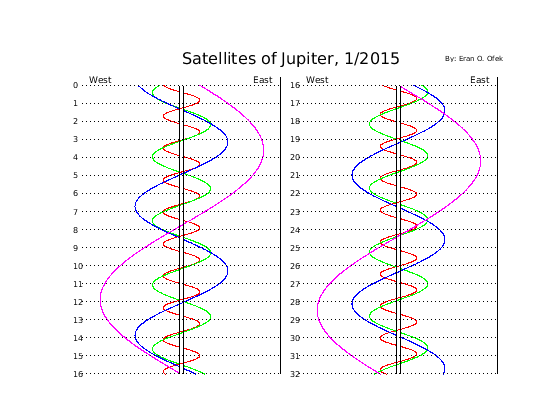

% January 2015:
celestial.SolarSys.jup_satcurve(1,2015)

You can calculate the Jupiter meridian as observed from Earth using: `celestial.SolarSys.jup_meridian` and you can plot the Jupiter map using:

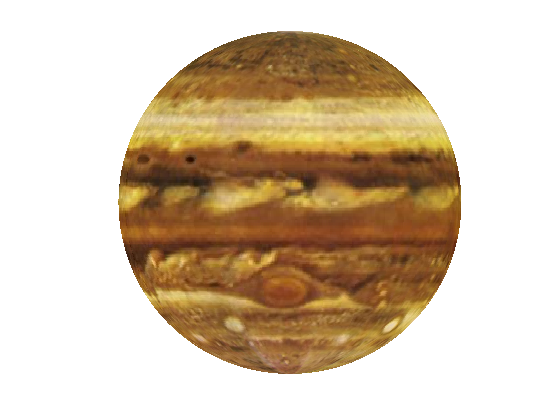

celestial.SolarSys.jupiter_map(celestial.time.julday([1 1 2015 23 0 0]))

**Phenomena**

There are several functions to calculate general phenomena.

Examples:

% Calculate the Moon phases in January 2015:
celestial.SolarSys.moon_phases([1 1 2015],[1 2 2015])

ans =             2    2.457e+06
            3    2.457e+06
            0    2.457e+06
            1    2.457e+06


% Approximate time for equinox and solstice between 2010 to 2020
Eq=celestial.SolarSys.equinox_solstice([2010;2020])

Eq =   1×4 struct array with fields:

    JD


There are several functions to calculation of conjunction of occultations and more.

## The stars package

Contain functions for stellar positions and constellations.

## The meteors package

Contains database of meteor showers and multi station meteors observing.

## The search pacakge

Contains functions to search for spherical coordinates in a table, and to match tables by spherical coordinates.